# Resolver ecuaciones diferenciales

## dsolve

Función de Matlab encargada de resolver ecuaciones diferenciales

## **Ejemplo 1 **

Resovler la ecuación logística $\frac{dN}{dt}= rN\left(1-\frac{N}{K}\right)$

syms N(t) r K
eqn = diff(N,t) == r*N*(1-N/K);     %Definición de ecuación diferencial
S = dsolve(eqn)                     %solución analítica de ecuación diferencial

$$S = \left(\begin{array}{c} \frac{K}{{\mathrm{e}}^{C_{1}-r\,t}+1}\\ 0\\ K \end{array}\right)$$

Se puede trabajar con el problema de valor inicial a través de definir una serie de casos :$N(0)=4,\,N(0)=20,\,N(0)=0$

syms y(t) eq
eqn = diff(N,t) == 0.5*N*(1-N/20);
CI1 = N(0) == 4;        %Escenario 1
S1 = dsolve(eqn,CI1)

$$S1 = \frac{20}{{\mathrm{e}}^{\log\left(4\right)-\frac{t}{2}}+1}$$

CI2 = N(0) == 20;       %Escenario 2
S2 = dsolve(eqn,CI2)

$$S2 = 20$$

CI3 = N(0) == 0;        %Escenario 3
S3 = dsolve(eqn,CI3)

$$S3 = 0$$

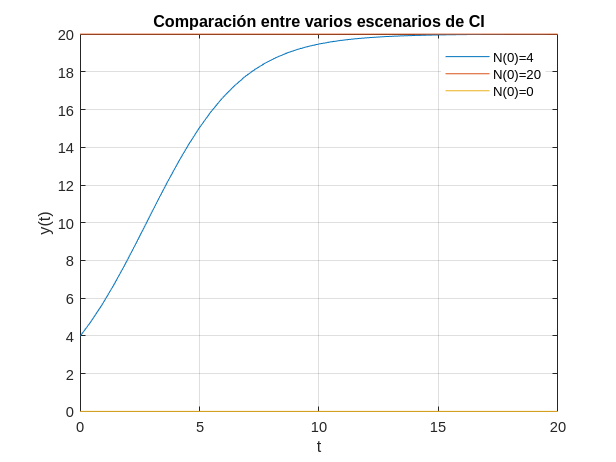

figure
fplot(S1,[0 20])
hold on
fplot(S2,[0 20])
fplot(S3,[0 20])
ylabel('y(t)')
xlabel('t')
grid on
legend({'N(0)=4', 'N(0)=20', 'N(0)=0'},"Box","off")
title("Comparación entre varios escenarios de CI")

## Ejemplo 2

Solucionar  $\frac{dy}{dt} = \frac{-t}{y}$

syms y(t); ecu = diff(y,t) == -t/y, dsolve(ecu)

$$ecu(t) = \frac{\partial }{\partial t}y\left(t\right)=-\frac{t}{y\left(t\right)}$$

$$ans = \left(\begin{array}{c} \sqrt{C_{1}-t^{2}}\\ -\sqrt{C_{1}-t^{2}} \end{array}\right)$$

Agregar condiciones iniciales $y(0)=2$

syms y(t); ecu = diff(y,t) == -t/y; ci = y(0) == 2; sol = dsolve(ecu,ci)

$$sol = \sqrt{4-t^{2}}$$

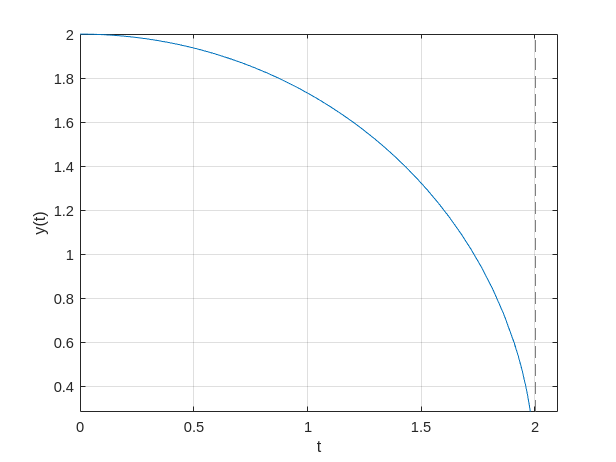

figure 
fplot(sol, [0 2.1])
grid on
ylabel('y(t)')
xlabel('t')

## Ejemplo 3

Solucionar la ecuación $(2t^2-y^2)dt+tydy =0$

En primer lugar, se podría llevar la expresión a la forma $\frac{dy}{dt}$.

En este caso sería: $\frac{dy}{dt}=-\frac{2}{y(t)/t} + \frac{y(t)}{t}$

Ahora podemos resolver la ecuación como en ejemplos anteriores:

syms y(t)
CI = y(2)==1;
equation = diff(y,t) == -2/(y/t) + y/t;
dsolve(equation);
SOL = dsolve(equation,CI)

$$SOL = \sqrt{2}\,t\,\sqrt{2\,\log\left(2\right)-2\,\log\left(t\right)+\frac{1}{8}}$$

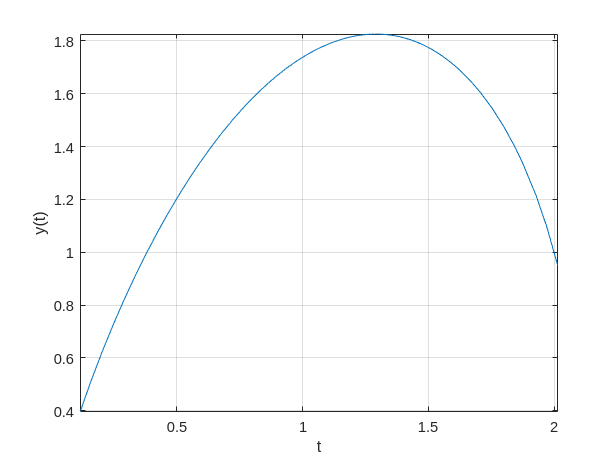

fplot(SOL)
grid on
ylabel('y(t)')
xlabel('t')

## Ejemplo 4

Solucionar la ecuación $\frac{dy}{dx} = y \sin(x)$

con $y(\pi) = -3$

**Solución analítica:**


$$y(x) = C \exp(-cos(x))$$


syms y(x)
ecu = diff(y,x,1) == y*sin(x);
ci = y(pi) == -3;
sol = dsolve(ecu,ci)

$$sol = -3\,{\mathrm{e}}^{-1}\,{\mathrm{e}}^{-\cos\left(x\right)}$$

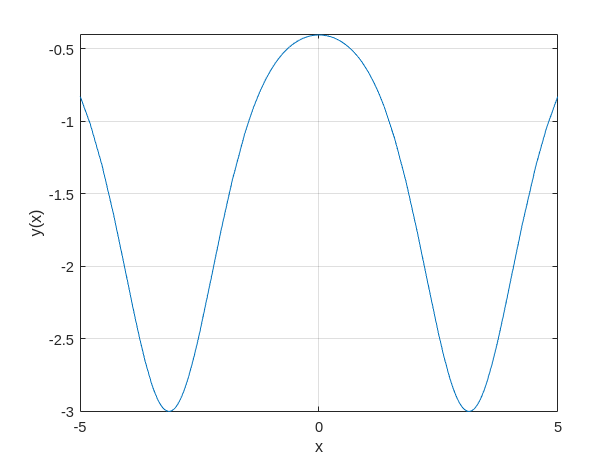

fplot(sol)
grid on
ylabel('y(x)')
xlabel('x')

## Ejemplo 5

Solucionar la ecuación $\frac{dy}{dx} + y^2=0$

con $y(0)=2$

**Solución analítica:**


$$y(t) = \frac{1}{x+c}$$


syms y(x)
ecu = diff(y,x,1) + y^2 == 0;
ci = y(0) == 2;
sol = dsolve(ecu,ci)

$$sol = \frac{1}{x+\frac{1}{2}}$$

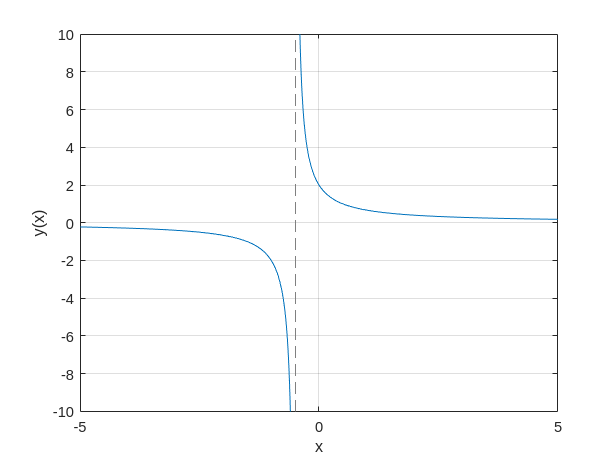

fplot(sol)
grid on
ylabel('y(x)')
xlabel('x')

## Ejemplo 6

Solucionar la ecuación $\frac{dy}{dt}+\frac{3}{t}y +2 =3t$

con $y(1) =1$

**Solución analítica:**


$$y(t) = \frac{6t^2 + 5t}{10} + ct^{-3}$$


syms y(t)
ecu = diff(y,t,1) + 3*(y/t) + 2 == 3*t;
ci = y(1) == 1;
sol = dsolve(ecu,ci)

$$sol = \frac{t\,\left(6\,t-5\right)}{10}+\frac{9}{10\,t^{3}}$$

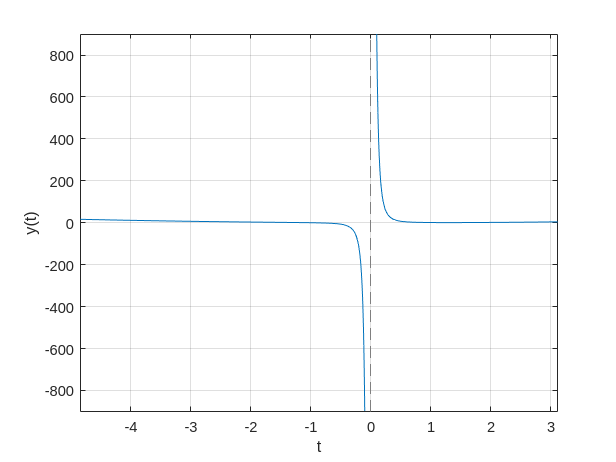

fplot(sol)
grid on
ylabel('y(t)')
xlabel('t')

## Ejemplo 7

Solucionar la ecuación $\frac{dy}{dt}+4y =e^{-t}$

con $y(0) = \frac{4}{3}$

**Solución analítica:**


$$\frac{1}{3}\exp(-t) + C \exp(-4t)$$


syms y(t)
ecu = diff(y,t,1) + 4*y == exp(-t);
ci = y(1) == 4/3;
sol = dsolve(ecu,ci)

$$sol = \frac{{\mathrm{e}}^{-t}}{3}-{\mathrm{e}}^{-4\,t}\,\left(\frac{{\mathrm{e}}^{3}}{3}-\frac{4\,{\mathrm{e}}^{4}}{3}\right)$$

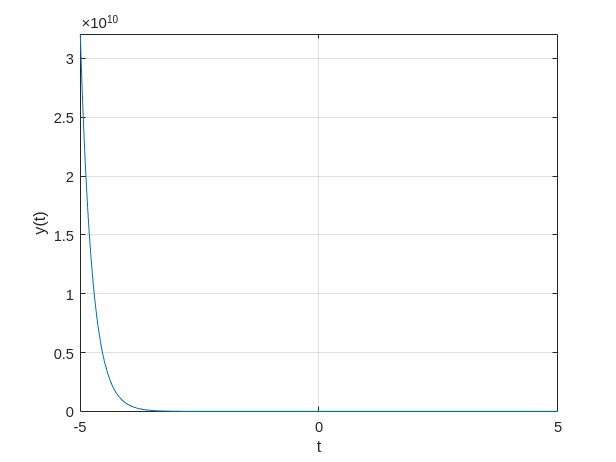

fplot(sol)
grid on
ylabel('y(t)')
xlabel('t')

## Aplicación

**Cuerpo en caída y resistencia del aire**

La ecuación diferencial que describe la velocidad de una masa $m$ que cae sujeta a una resistencia del aire proporcional a la velocidad instantánea $v(t)$ es:


$$m \frac{dv}{dt}=mg-kv$$


donde $k>0$ es una constante de proporcionalidad y, $g$ es la aceleración de la gravedad.

**a) **Resuelva la ecuación anterior de forma analítica y simbólica asumiendo que


$$m = 10^{-3}kg$$



$$g=9.8 m/s^2$$



$$k = 10^{-4}$$



$$v(0) = 0$$


Compare las soluciones. ¿Coinciden?

**Solución analítica:**


$$v(t) = \frac{mg}{k} + C \exp(-\frac{k}{m}t)$$


syms v(t) 
m = 10^(-3);
g = 9.8;
k = 10^(-4);

eq1 = m*diff(v,t) == m*g - k*v;  
ci = v(0) == 0;

sol = dsolve(eq1,ci)

$$sol = 98-98\,{\mathrm{e}}^{-\frac{t}{10}}$$

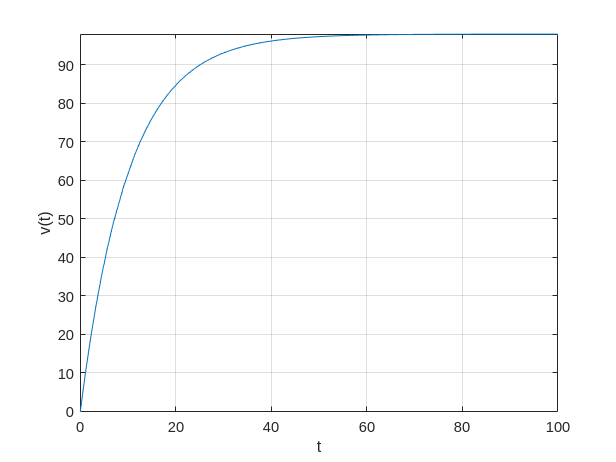

fplot(sol,[0 100])
grid on
ylabel('v(t)')
xlabel('t')

**b)** Determinar la velocidad límite de la masa.

Esta velocidad límite se obtiene calculando el límite 


$$v_{lim} = \lim_{t\rightarrow \infty} v(t)$$


donde $v(t)$ es la velocidad obtenida en el ítem (a). Para este fin, grafique la solución del problema en un intervalo suficientemente largo como para estimar esta velocidad límite.

**Solución analítica:**

¿la estimación de la velocidad límite obtenida de la gráfica coincide con el valor teórico obtenido de la solución analítica?

limit(sol,inf)

$$ans = 98$$